% coordinate of each pixel
for n=1 : NCell

    [Coomasqx(n), Coomasqy(n)] = ind2sub([sizey, sizex], n);

end

k = 0;
assembly_nonortho=[];

for i = 1:NClOK
    k = k+1;
    % assembly_nonortho{k} = transpose(find(CellClraw(i,:)==1));
    assembly_nonortho{k} = find(CellClraw(i,:)==1);
end


    colors = [
    1 0 0;     % Red
    0 1 0;     % Green
    0 0 1;     % Blue
    1 1 0;     % Yellow
    1 0 1;     % Magenta
    0 1 1;     % Cyan
    0.5 0 0;   % Maroon
    0 0.5 0;   % Olive
    0 0 0.5;   % Navy
    0.5 0.5 0; % Olive Green
    0.5 0 0.5; % Purple
    0 0.5 0.5; % Teal
    0.75 0 0;  % Dark Red
    0 0.75 0;  % Lime Green
    0 0 0.75;  % Dark Blue
    0.75 0.75 0; % Dark Yellow
    0.75 0 0.75; % Dark Magenta
    0 0.75 0.75; % Dark Cyan
];



idassembly=zeros(NCell,1);
listcellassembly=[];
assembly=assembly_nonortho;
%assembly=assemblystat;
%assembly=assemblyraw;
nbassemblies=length(assembly);

for n=1:nbassemblies
    idassembly(assemblyortho{n})=n;
    listcellassembly=[listcellassembly assemblyortho{n}];
    sumSCEpercluster(n)=sum(IDX2==n);
end

NCl = max(IDX2);
[~,x2] = sort(IDX2);
MSort = M(x2,x2);

% figure
% 
% % imagesc(calcium);
% % colormap (gray)
% % clim ([0 300])
% 
% hold on
% 
% for n=11:NCell
% 
%     x=cell2mat(outline_gcampx(n));
%     y=cell2mat(outline_gcampy(n));
% 
%     plot(x, y, '.', 'MarkerSize', 4,"Color",colors(idassembly(n),:));
%    % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
% end
% axis image
% axis off
% hold off
% title ('calcium')
% hold off

background=zeros(sizex,sizey);
% figure
% image(background);
% hold on


for num=1:nbassemblies
    x=[];
    y=[];
    for n=cell2mat(assembly_nonortho(num))
            x=[x Coomasqx(n)];
            y=[y Coomasqy(n)];
            % sorted_indices = convhull(x, y); 
            % x = x(sorted_indices);
            % y = y(sorted_indices);
            % scatter(x, y,100,colors(num,:),'filled','square')
             % patch(x, y,'w','FaceAlpha', 0.5,'EdgeColor',colors(num,:),'LineWidth',1)
            % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
            % plot(x, y, '.', 'MarkerSize', 4,"Color",col);
            % hold on
    end
    figure
    image(background);
    hold on
    scatter(x, y,100,colors(num,:),'filled','square')%,'MarkerFaceAlpha',0.3)
    xlim ([0 sizex+1])
    ylim ([0 sizey+1])
    hold off

    % axis off
    % box on
    % % Find the convex hull (edges) of the points
    % k = boundary(x', y');
    % 
    % % Plot the original points
    % scatter(x, y, 'b', 'filled');
    % hold on;
    % 
    % % Plot the edges
    % plot(x(k), y(k), 'r', 'LineWidth', 2);
    % % sorted_indices = convhull(x, y);
    % % x = x(sorted_indices);
    % % y = y(sorted_indices);
    % patch(x, y,'w','FaceAlpha', 0.5,'EdgeColor',colors(num,:),'FaceColor',colors(num,:),'LineWidth',1)
    %hold on
    namegraph=strcat(['assembly' num2str(num) '.png']);
    exportgraphics(gcf,[namefull namegraph],'Resolution',300);
end
%hold off
% xlim ([0 sizex])
% ylim ([0 sizey])
% axis off
% box on
% colormap (gray)
% axis off
% axis image
% hold off

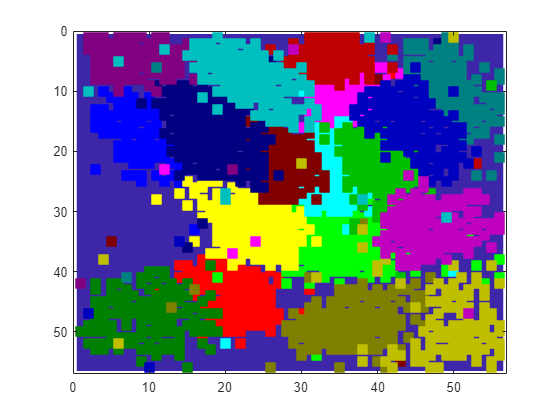

background=zeros(sizex,sizey);
figure
image(background);
hold on


for num=1:nbassemblies
    x=[];
    y=[];
    for n=cell2mat(assembly_nonortho(num))
            x=[x Coomasqx(n)];
            y=[y Coomasqy(n)];
    end
    %figure
    % image(background);
    % hold on
    scatter(x, y,100,colors(num,:),'filled','square')%,'MarkerFaceAlpha',0.3)
    xlim ([0 sizex+1])
    ylim ([0 sizey+1])
    

    % axis off
    % box on
    % % Find the convex hull (edges) of the points
    % k = boundary(x', y');
    % 
    % % Plot the original points
    % scatter(x, y, 'b', 'filled');
    % hold on;
    % 
    % % % Plot the edges
    % plot(x(k), y(k), 'r', 'LineWidth', 2);
    % hold on
    % sorted_indices = convhull(x, y);
    % x = x(sorted_indices);
    % y = y(sorted_indices);
    % patch(x, y,'w','FaceAlpha', 0.5,'EdgeColor',colors(num,:),'FaceColor',colors(num,:),'LineWidth',1)
    %hold on
end
hold off  

namegraph='allassembly.png';
    exportgraphics(gcf,[namefull namegraph],'Resolution',300);
hold off
return

% k=0
% for i = 1:NClOK
%     if length(find(CellClraw(i,:)))>5 % is this the limit of cell per assembly ???it seems
%         k = k+1;
%         assembly_nonortho{k} = find(CellClraw(i,:));
%     end
% end
% % assembly_nonortho=C0;


assembly=assembly_nonortho;
% assembly=assemblyraw;

% figure
% image(background);
% background=zeros(512,512);
for numa=1:nbassemblies-1

for num=numa+1:nbassemblies
figure
image(background);
background=zeros(512,512);
    for n=cell2mat(assembly(numa))
            x=cell2mat(outline_gcampx(n));
            y=cell2mat(outline_gcampy(n));
            sorted_indices = convhull(x, y); 
            x = x(sorted_indices);
            y = y(sorted_indices);
            patch(x, y,colors(numa,:),'FaceAlpha', 0.5)
             % patch(x, y,'w','FaceAlpha', 0.5,'EdgeColor',colors(num,:),'LineWidth',1)
            % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
            % plot(x, y, '.', 'MarkerSize', 4,"Color",col);
    end
        for n=cell2mat(assembly(num))
            x=cell2mat(outline_gcampx(n));
            y=cell2mat(outline_gcampy(n));
            sorted_indices = convhull(x, y); 
            x = x(sorted_indices);
            y = y(sorted_indices);
            patch(x, y,colors(num,:),'FaceAlpha', 0.5)
             % patch(x, y,'w','FaceAlpha', 0.5,'EdgeColor',colors(num,:),'LineWidth',1)
            % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
            % plot(x, y, '.', 'MarkerSize', 4,"Color",col);
    end
axis off
axis image
    % hold on
end
end
colormap (gray)
axis off
axis image

% mdl = fitlm(X_train, Y_train);